% Arteriosclerosis Simulation - Testing Different Compliance Values
% This script tests different arterial compliance values to simulate
% arteriosclerosis and achieve target pressures of 140/65 and 180/50 mmHg

clear all
close all
clc

fprintf('=== ARTERIOSCLEROSIS SIMULATION ===\n');

=== ARTERIOSCLEROSIS SIMULATION ===


fprintf('Testing different compliance values to simulate arterial stiffening\n\n');

Testing different compliance values to simulate arterial stiffening




% Test different compliance values
compliance_values = [0.0015, 0.0014, 0.0013, 0.0012, 0.0011, 0.0010, 0.0009, 0.0008];
target_pressures = [140, 65; 180, 50]; % [systolic, diastolic] for each target

fprintf('Testing compliance values: ');

Testing compliance values: 

fprintf('%.4f ', compliance_values);

0.0015 0.0014 0.0013 0.0012 0.0011 0.0010 0.0009 0.0008 

fprintf('\n\n');


% Initialize results storage
results = zeros(length(compliance_values), 3); % [compliance, systolic, diastolic]

% Loop through different compliance values
for i = 1:length(compliance_values)
    % Set up parameters with current compliance value
    global T TS TMAX QMAX Rs Csa dt;
    T = 0.0125;        % Duration of heartbeat (minutes) --> 80 beats/min
    TS = 0.4*T;        % Duration of systole (minutes)
    TMAX = 0.16*T;     % Time at which flow is max (minutes)
    QMAX = 28;         % Max flow through aortic valve (liters/minute)
    Rs = 17.86;        % Systemic resistance (mmHg/(liter/minute)) - Normal
    Csa = compliance_values(i);  % Current compliance value
    dt = 0.01*T;       % Time step duration (minutes)
    klokmax = ceil(16*T/dt); % Total number of timesteps
    Psa = 80;          % Starting (diastolic) value of arterial pressure (mmHg)
    

    % Initialize arrays
    t_plot = zeros(1, klokmax);
    QAo_plot = zeros(1, klokmax);
    Psa_plot = zeros(1, klokmax);
    
    % Run simulation
    for klok = 1:klokmax
        t = klok*dt;
        QAo = QAo_now(t);
        Psa = Psa_new(Psa, QAo);
        t_plot(klok) = t;
        QAo_plot(klok) = QAo;
        Psa_plot(klok) = Psa;
    end
    
    % Calculate final values from last 4 cycles
    cycles_to_use = 4;
    cycle_length = round(T/dt);

Csa = 0.0015 L/mmHg: Systolic = 114.8, Diastolic = 85.2 mmHg, CO = 5.60 L/min


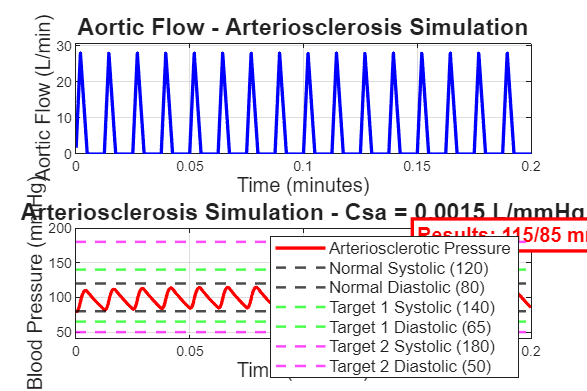

Csa = 0.0014 L/mmHg: Systolic = 115.9, Diastolic = 84.1 mmHg, CO = 5.60 L/min


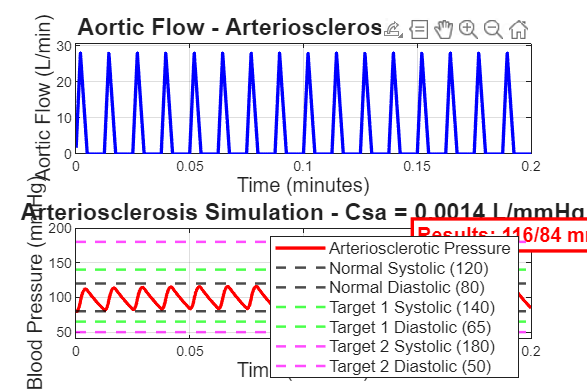

Csa = 0.0013 L/mmHg: Systolic = 117.1, Diastolic = 83.0 mmHg, CO = 5.60 L/min


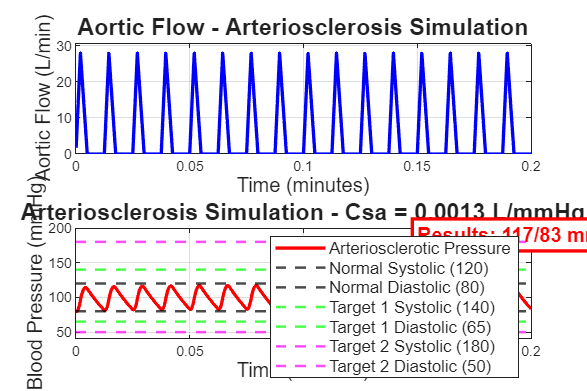

Csa = 0.0012 L/mmHg: Systolic = 118.6, Diastolic = 81.6 mmHg, CO = 5.60 L/min


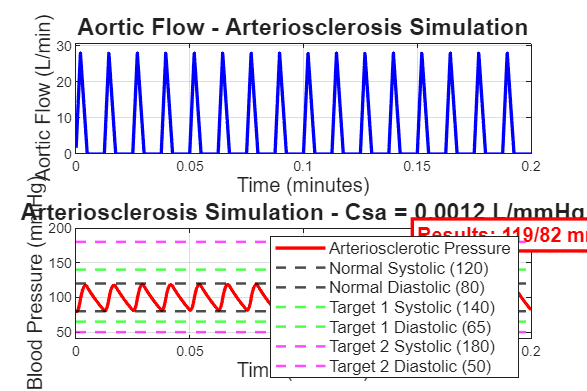

Csa = 0.0011 L/mmHg: Systolic = 120.3, Diastolic = 80.1 mmHg, CO = 5.60 L/min


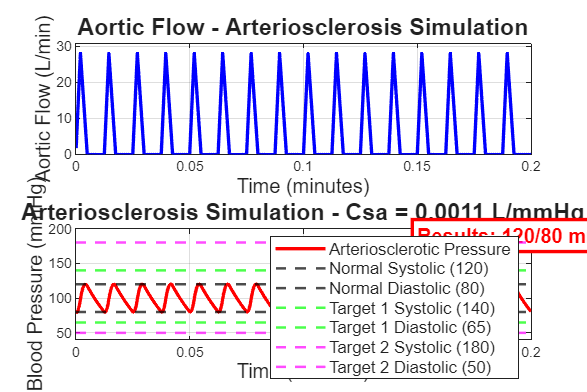

Csa = 0.0010 L/mmHg: Systolic = 122.4, Diastolic = 78.2 mmHg, CO = 5.60 L/min


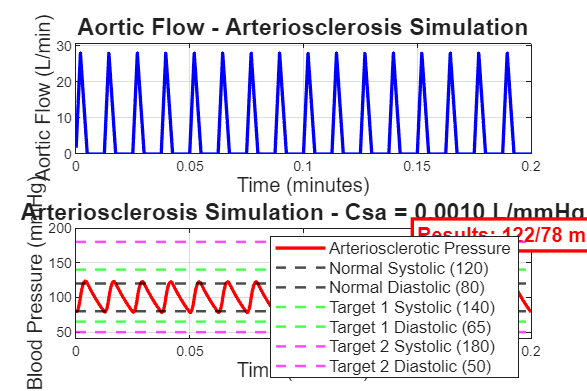

Csa = 0.0009 L/mmHg: Systolic = 124.9, Diastolic = 75.9 mmHg, CO = 5.60 L/min


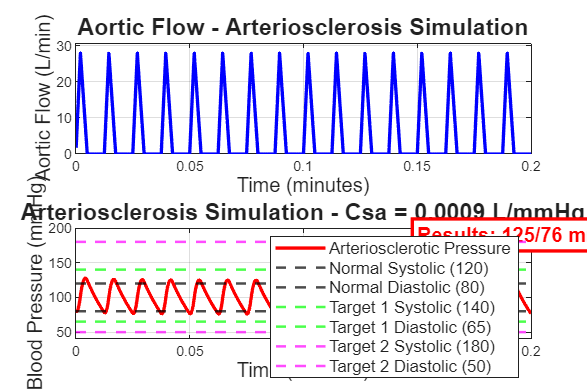

Csa = 0.0008 L/mmHg: Systolic = 128.1, Diastolic = 73.2 mmHg, CO = 5.60 L/min


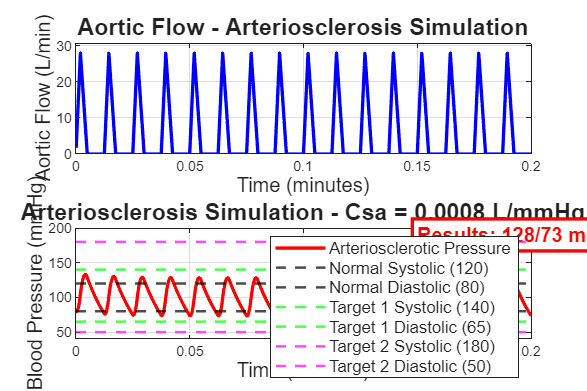

    start_idx = klokmax - cycles_to_use * cycle_length + 1;
    pressure_data = Psa_plot(start_idx:end);
    systolic = max(pressure_data);
    diastolic = min(pressure_data);
    cardiac_output = mean(QAo_plot(start_idx:end));
    
    % Store results
    results(i, :) = [Csa, systolic, diastolic];
    
    % Display results
    fprintf('Csa = %.4f L/mmHg: Systolic = %.1f, Diastolic = %.1f mmHg, CO = %.2f L/min\n', ...
        Csa, systolic, diastolic, cardiac_output);
    
    % Create plot for this compliance value
    figure('color','white', 'Position', [50, 50, 1200, 800])
    
    % Upper subplot: Aortic Flow
    subplot(2,1,1)

    plot(t_plot, QAo_plot, 'b-', 'linewidth', 2)
    xlabel('Time (minutes)', 'FontSize', 12)
    ylabel('Aortic Flow (L/min)', 'FontSize', 12)
    title('Aortic Flow - Arteriosclerosis Simulation', 'FontSize', 14)
    grid on
    axis([0, max(t_plot), 0, max(QAo_plot)*1.1])
    
    % Lower subplot: Arterial Pressure
    subplot(2,1,2)
    plot(t_plot, Psa_plot, 'r-', 'linewidth', 2)
    xlabel('Time (minutes)', 'FontSize', 12)
    ylabel('Blood Pressure (mmHg)', 'FontSize', 12)
    title(sprintf('Arteriosclerosis Simulation - Csa = %.4f L/mmHg', Csa), 'FontSize', 14)
    grid on
    axis([0, max(t_plot), 40, 200])
    
    % Add reference lines
    yline(120, '--k', 'LineWidth', 1.5)

    yline(80, '--k', 'LineWidth', 1.5)
    yline(140, '--g', 'LineWidth', 1.5)
    yline(65, '--g', 'LineWidth', 1.5)
    yline(180, '--m', 'LineWidth', 1.5)
    yline(50, '--m', 'LineWidth', 1.5)
    
    % Add legend
    legend('Arteriosclerotic Pressure', 'Normal Systolic (120)', 'Normal Diastolic (80)', ...
           'Target 1 Systolic (140)', 'Target 1 Diastolic (65)', ...
           'Target 2 Systolic (180)', 'Target 2 Diastolic (50)', ...
           'Location', 'northeast', 'FontSize', 10)
    
    % Add text annotation with results
    text(0.15, 190, sprintf('Results: %.0f/%.0f mmHg', systolic, diastolic), ...
        'FontSize', 12, 'FontWeight', 'bold', 'Color', 'red', ...
        'BackgroundColor', 'white', 'EdgeColor', 'red', 'LineWidth', 2)
    
    % Pause to see each plot
    pause(1);
end


% Find best compliance values for target pressures
fprintf('\n=== TARGET PRESSURE ANALYSIS ===\n');


=== TARGET PRESSURE ANALYSIS ===



% Find compliance for 140/65 mmHg
target1_systolic = 140;
target1_diastolic = 65;
error1 = abs(results(:,2) - target1_systolic) + abs(results(:,3) - target1_diastolic);
[~, idx1] = min(error1);
best_compliance_1 = results(idx1, 1);

% Find compliance for 180/50 mmHg
target2_systolic = 180;
target2_diastolic = 50;
error2 = abs(results(:,2) - target2_systolic) + abs(results(:,3) - target2_diastolic);
[~, idx2] = min(error2);
best_compliance_2 = results(idx2, 1);

fprintf('Best compliance for 140/65 mmHg: Csa = %.4f L/mmHg\n', best_compliance_1);

Best compliance for 140/65 mmHg: Csa = 0.0008 L/mmHg


fprintf('Achieved: %.1f/%.1f mmHg\n', results(idx1,2), results(idx1,3));

Achieved: 128.1/73.2 mmHg


fprintf('\nBest compliance for 180/50 mmHg: Csa = %.4f L/mmHg\n', best_compliance_2);


Best compliance for 180/50 mmHg: Csa = 0.0008 L/mmHg


fprintf('Achieved: %.1f/%.1f mmHg\n', results(idx2,2), results(idx2,3));

Achieved: 128.1/73.2 mmHg



fprintf('\n=== SUMMARY ===\n');


=== SUMMARY ===


fprintf('Arteriosclerosis simulation complete!\n');

Arteriosclerosis simulation complete!


fprintf('Compliance values tested: %.4f to %.4f L/mmHg\n', min(compliance_values), max(compliance_values));

Compliance values tested: 0.0008 to 0.0015 L/mmHg


fprintf('Results show how decreased compliance (arterial stiffening) increases systolic pressure\n');

Results show how decreased compliance (arterial stiffening) increases systolic pressure


fprintf('and pulse pressure, matching clinical presentation of arteriosclerosis.\n');

and pulse pressure, matching clinical presentation of arteriosclerosis.
